# **Two Goods Model**

## A Model with Two Goods

A consumer, with preference $U(x_1,x_2)$ and $M$ dollars, chooses between two goods, $x_1$ and $x_2$, that cost $p_1$ and $p_2$ per unit of good.

## Model Parameters

grid_points = 100;
% Cobb Douglas Utility
alpha = 0.5;
beta = 1-alpha;
% Budget
M = 100;
p1 = 10;
p2 = 15;

## Preference

Consumers have preference over the two goods, where $U(x_1,x_2)$ represents the number assigned by the utility function to the goods bundle $(x_1, x_2)$.

If households enjoy both goods as complements, we could use this Cobb-Douglas form with Constant Return to Scale to represent Utility:

 
$$U(x_1,x_2) = x_1^{\alpha} \cdot x_2^{1-\alpha}$$


We can use matlab to graph the indifference curves as contour plots:

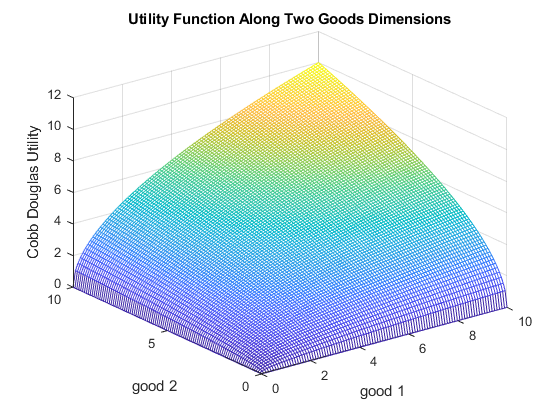

close all;
figure();
x1 = linspace(0,10,grid_points);
x2 = linspace(0,10,grid_points);
[x1mesh, x2mesh] = meshgrid(x1,x2);
U = (x1mesh.^alpha).*(x2mesh.^beta);mesh(x1mesh,x2mesh,U)
xlabel('good 1');
ylabel('good 2');
zlabel('Cobb Douglas Utility');
title('Utility Function Along Two Goods Dimensions')

## Budget

The budget (choice) set facing the household could be written as:


$$B = \{ (x_1, x_2) : x_1 \ge 0, x_2 \ge 0, p_1 x_1 + p_2 x_2 \le M \}$$


where $M$ is the total resource available for the household. 

We can plot out the budget set graphically:

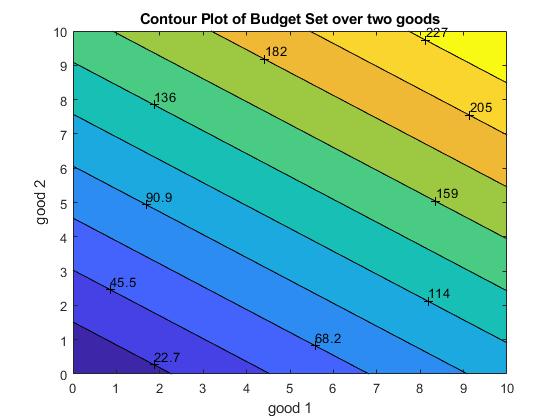

figure();
x1 = linspace(0,10,grid_points);
x2 = linspace(0,10,grid_points);
[x1mesh_cost, x2mesh_cost] = meshgrid(x1,x2);
bundle_cost = x1mesh_cost*p1 + x2mesh_cost*p2;
figure();
contour = contourf(x1mesh_cost, x2mesh_cost, bundle_cost, 10);
clabel(contour);
xlabel('good 1');
ylabel('good 2');
zlabel('Cost');
title('Contour Plot of Budget Set over two goods')

## Budget and Preference

Budget and Indifference Together

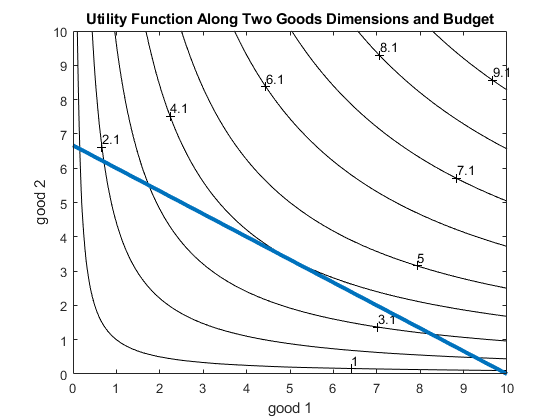

figure();
contour_u = contourf(x1mesh, x2mesh, U, [2.1,3.1,4.1,5,1,6.1,7.1,8.1,9.1]);
clabel(contour_u);
colormap('white')
xlabel('good 1');
ylabel('good 2');
zlabel('Cobb Douglas Utility');
title('Utility Function Along Two Goods Dimensions and Budget')
grid_points = 100;
x1_M = linspace(0,10,grid_points);
x2_M = (M-x1*p1)/p2;
hold on;
plot(x1_M, x2_M, 'LineWidth', 3);